# Homework 1 - ECE 4560

Brett Erickson

Source code can be found at 

[https://github.com/berickon3/ECE-4560-Robotics-Code/](https://github.com/berickon3/ECE-4560-Robotics-Code/)

% Import own library
import robotics.*

1) 3 hours of work, primarily because I wanted to make a package to handle transforms.

2)

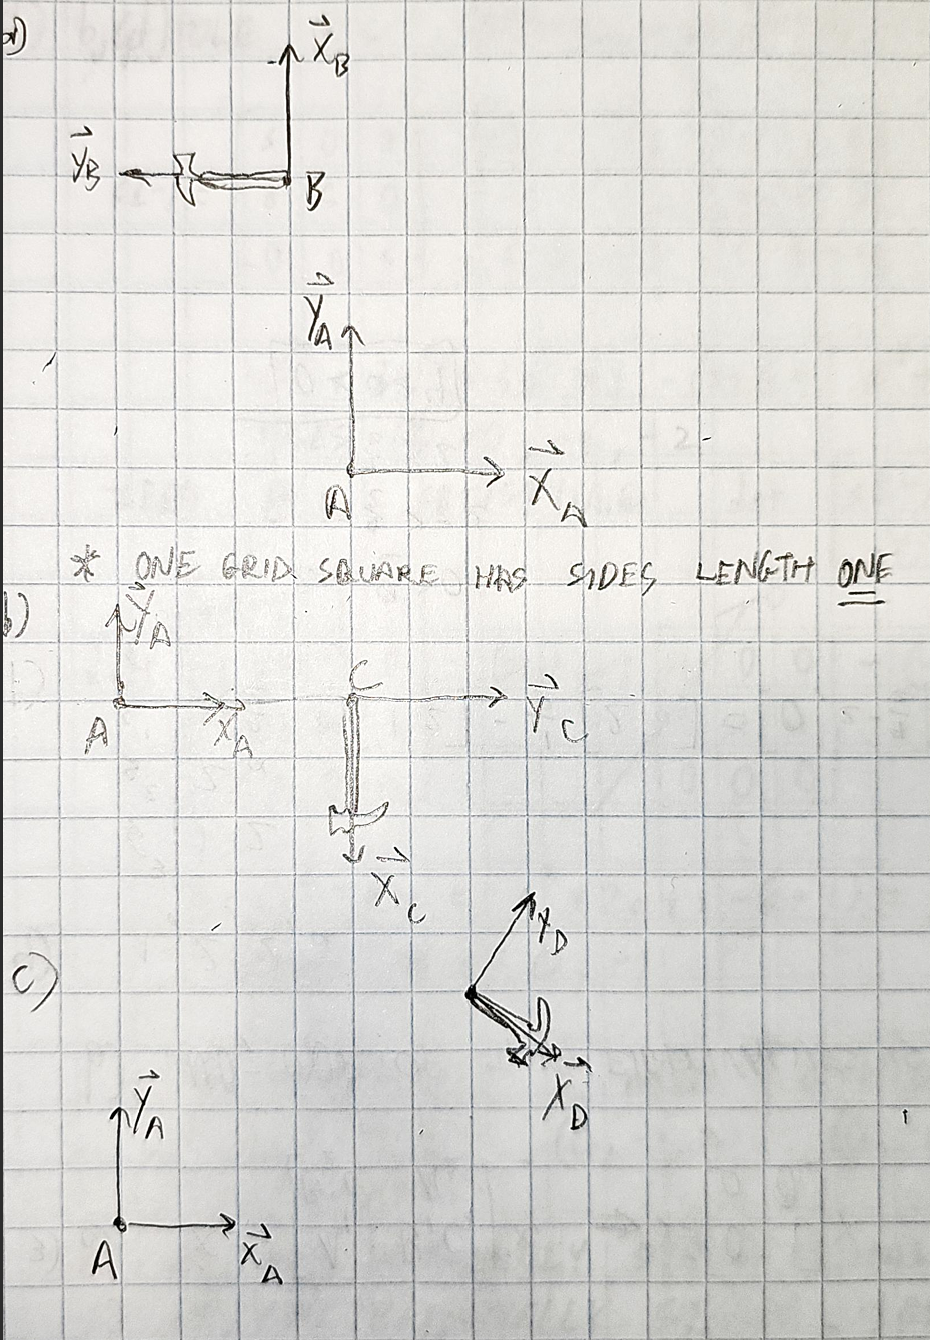

3)

The function planarTranslation2d I wrote takes arguments containing the point in xy, displacment in xy, and rotation as theta in radians.

The rotation matrix is:


$$\left\lbrack \begin{array}{cc}
\cos \left(\theta \right) & -\sin \left(\theta \right)\\
\sin \left(\theta \right) & \cos \left(\theta \right)
\end{array}\right\rbrack$$


point = [2;0];
theta = pi;
displacement = [-1;5];

planarTranslation2d(point,displacement,theta)

ans =     -3
     5



theta = -pi/2;
displacement = [4;0];

planarTranslation2d(point,displacement,theta)

ans =      4
    -2



theta = -pi/6;
displacement = [6;4];

planarTranslation2d(point,displacement,theta)

ans =     7.7321
    3.0000


4)

Following problem 3, I realized it would be easier to treat each transform as an object and define operations that can be done with them as functions. The transform2d.m file defines the class and gives functions for instantiation, point transformation, and composition of multiple transforms. 

world_transform = transform2d([2;4], -pi/2);
B_transform = transform2d([-1;5],pi);
C_transform = transform2d([4;0],-pi/2);
D_transform = transform2d([6;4],-pi/6);

world_B_transform = world_transform.compose(B_transform);
world_C_transform = world_transform.compose(C_transform);
world_D_transform = world_transform.compose(D_transform);

world_B_transform.pointOperation(point)

ans =      9
    11


world_C_transform.pointOperation(point)

ans =     2.0000
    4.0000


world_D_transform.pointOperation(point)

ans =     7.0000
    0.2679


5)

a) displacement = $\left\lbrack \begin{array}{c}
-6\\
2
\end{array}\right\rbrack$ theta = -$\frac{\pi }{2}$

b) displacement = $\left\lbrack \begin{array}{c}
2\\
6
\end{array}\right\rbrack$ theta = $\frac{\pi }{2}$

c) 

AB_transform = transform2d([-6; 2], -pi/2);
AB_transform.rotation

ans =     0.0000    1.0000
   -1.0000    0.0000



$$g_{\mathrm{AB}} =\left(\left\lbrack \begin{array}{c}
-6\\
2
\end{array}\right\rbrack ,\left\lbrack \begin{array}{cc}
0 & 1\\
-1 & 0
\end{array}\right\rbrack \right)$$


6)

a) Visited and help with partial assembly of SO-101 leader

b) I am most interested in the SO-101 platform. For one, it is open source and can be combined with the Hugging Face LeRobot machine learning library. I've got an Nvidia Jetson at home, so maybe I can leverage that. Also it is low cost, so I just bought the parts to work on it at home. 